% Rocky_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% Currently no motor model (M =1).Placeholder for motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki and Kp to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/12/21 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                 % TF of motor
%M = 1;                          % TF without motor  
AddedThings = (Jp)+(Ji/s)+(Ci/s^2);
Motorloop = M/(1+M*AddedThings);
%closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*K*Motorloop)  

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{a+s}+1\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (Ki + Kp s)
  -------------------------------------------------------- - 1
        2          2    3                    2
  (- l s  + g) (a s  + s  + Ci a b + Jp a b s  + Ji a b s)




% Substitute parameters and solve
% system parameters
g = 9.81;
l = 22*2.54/100;  %effective length 
a = 14;           %nomical motor parameters
b = 1/400;        %nomical motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{175\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{2794\,\left(s^{2}-\frac{24525}{1397}\right)\,\left(\frac{7\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{200\,\left(s+14\right)}+1\right)\,\left(s+14\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 
p1 = -1 + 10*pi*i;
p2 = -1 - 10*pi*i;
p3 = -0.5;
p4 = -1;
p5 = -1;

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$tgt\_char\_poly = {\left(s+1\right)}^{2}\,\left(s+\frac{1}{2}\right)\,\left(s+1-10\,\pi \,\mathrm{i}\right)\,\left(s+1+10\,\pi \,\mathrm{i}\right)$$


% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = \left(1397\,s^{2}-24525\right)\,\left(7\,\text{Ci}+7\,\mathrm{Ji}\,s+7\,\mathrm{Jp}\,s^{2}+2800\,s^{2}+200\,s^{3}\right)$$

$$d = 9779\,\text{Ci}\,s^{2}-171675\,\mathrm{Ji}\,s-171675\,\text{Ci}+9779\,\mathrm{Ji}\,s^{3}-171675\,\mathrm{Jp}\,s^{2}+9779\,\mathrm{Jp}\,s^{4}+17500\,\mathrm{Ki}\,s^{2}+17500\,\mathrm{Kp}\,s^{3}-68670000\,s^{2}-4905000\,s^{3}+3911600\,s^{4}+279400\,s^{5}$$

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccccc} -171675\,\text{Ci} & -171675\,\mathrm{Ji} & 9779\,\text{Ci}-171675\,\mathrm{Jp}+17500\,\mathrm{Ki}-68670000 & 9779\,\mathrm{Ji}+17500\,\mathrm{Kp}-4905000 & 9779\,\mathrm{Jp}+3911600 & 279400 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccccc} -\frac{6867\,\text{Ci}}{11176} & -\frac{6867\,\mathrm{Ji}}{11176} & \frac{7\,\text{Ci}}{200}-\frac{6867\,\mathrm{Jp}}{11176}+\frac{175\,\mathrm{Ki}}{2794}-\frac{343350}{1397} & \frac{7\,\mathrm{Ji}}{200}+\frac{175\,\mathrm{Kp}}{2794}-\frac{24525}{1397} & \frac{7\,\mathrm{Jp}}{200}+14 & 1 \end{array}\right)$$


% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \begin{array}{l} \left(\begin{array}{cccccc} -\left(-\frac{1}{2}+5\,\pi \,\mathrm{i}\right)\,\sigma_{1} & \frac{1}{2}-\sigma_{1}\,\left(-\frac{5}{2}+20\,\pi \,\mathrm{i}\right)-5\,\pi \,\mathrm{i} & \frac{5}{2}-\sigma_{1}\,\left(-\frac{9}{2}+25\,\pi \,\mathrm{i}\right)-20\,\pi \,\mathrm{i} & \frac{9}{2}-\sigma_{1}\,\left(-\frac{7}{2}+10\,\pi \,\mathrm{i}\right)-25\,\pi \,\mathrm{i} & \frac{9}{2} & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1+10\,\pi \,\mathrm{i} \end{array}$$


% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
%solutions = solve(coeffs_denom(1:2) == coeffs_tgt(1:2),  Kp, Ki)
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5),  Kp, Ki,Jp,Ji,Ci)

solutions = struct with fields:
    Kp: 1513255684/4291875 - (2794*(1 + pi*10i)*(- 7/2 + pi*10i))/175 - (3903218*(1 + pi*10i)*(- 5/2 + pi*20i))/4291875 - (pi*346517468i)/858375
    Ki: 6506/5 - (3903218*(- 1/2 + pi*5i)*(1 + pi*10i))/4291875 - (2794*(1 + pi*10i)*(- 9/2 + pi*25i))/175 - (pi*11176i)/35
    Jp: -1900/7
    Ji: (pi*55880i)/6867 + (11176*(1 + pi*10i)*(- 5/2 + pi*20i))/6867 - 5588/6867
    Ci: (11176*(- 1/2 + pi*5i)*(1 + pi*10i))/6867



% display the solutions as double precision numbers
Kp = double(solutions.Kp);
Ki = double(solutions.Ki);
Jp = double(solutions.Jp);
Ji = double(solutions.Ji);
Ci = double(solutions.Ci);
solutions_table = table([Kp;Ki;Jp;Ji;Ci],real([Kp;Ki;Jp;Ji;Ci]),'RowNames',{'Kp','Ki','Jp','Ji','Ci'},VariableNames={'Solutions','Real Part'})

solutions_table = 5×2 table
               Solutions         Real Part
          ___________________    _________

    Kp      17963-2.9159e-69i       17963 
    Ki      41216+0i                41216 
    Jp    -271.43+0i              -271.43 
    Ji    -3217.4-1.0867e-70i     -3217.4 
    Ci    -803.95+0i              -803.95 



% Location of the poles of the closed-loop TF.
% NOTE there are only 2 unknowns but 3 polynomial coefficients so 
% the problem is underdetermined and the closed loop poles don't exact
% match the target poles. 
% use trial-and-error to tune response
closed_loop_poles = vpa (roots(subs(coeffs_denom)), 4)

$$closed\_loop\_poles = \left(\begin{array}{c} -0.001012-0.0318\,\mathrm{i}\\ -0.001012+0.0318\,\mathrm{i}\\ -1.0\\ -1.0\\ -2.0 \end{array}\right)$$


% Plot impulse response of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
                                                                                                                               
  1.056e28 s^8 + 1.953e29 s^7 - (7.09e29+4.015e-44i) s^6 - (2.037e31+5.62e-43i) s^5 + (5.035e30+7.048e-43i) s^4 + (2.974e32    
                                                                                                                               
                                                                                                  +9.867e-42i) s^3 + 7.3e31 s^2
                                                                                                                               
  -----------------------------------------------------------------------------------------------------------------------------
                                                                                                                               
  1.056e28 s^8 + 1.953e29 s^7 + (1.117e31-1.968e-42i) s^6 + (1.731e32-2.755e-41i) s^5 + (3.865e3

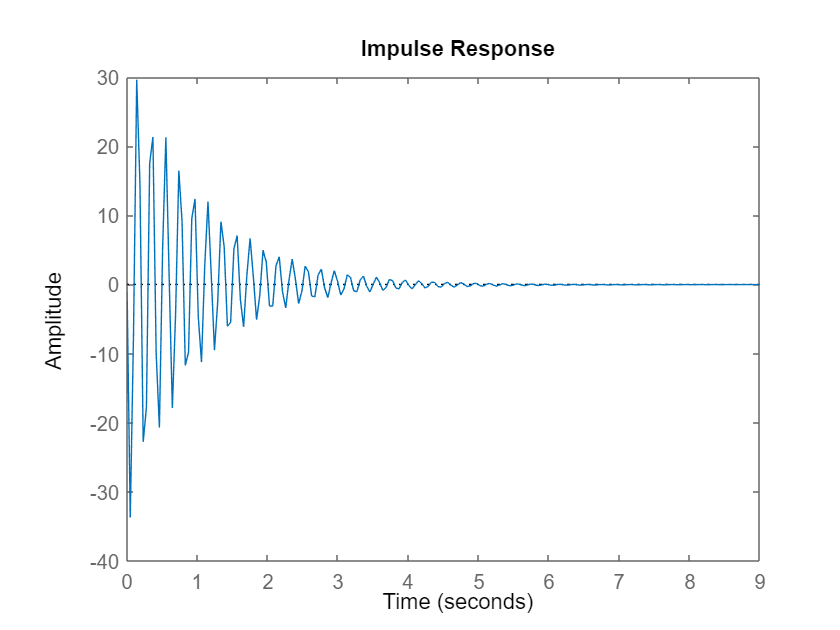

    figure (1)
    impulse(TFH);   %plot the impulse reponse

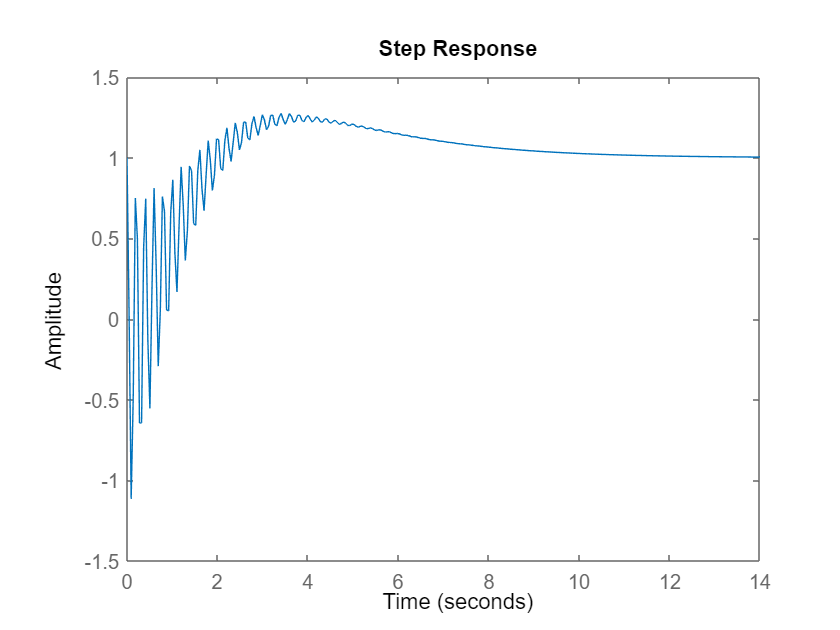

    figure(2)
    step(TFH)